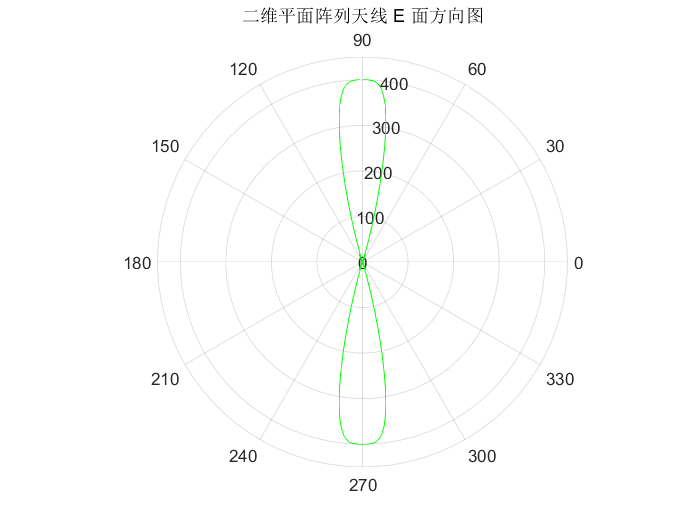

clear all;close all;clc;
%% 相控阵天线参数设置
l=1;         %信号波长
d=l/2;       %半波振子天线之间的间距
k=2*pi/l;    %传播常数
m=20;
n=20;        %二维阵列元数
theta=linspace(0,2*pi,400);
phi=linspace(0,2*pi,400);%角度范围，水平方位角和竖直方位角
a1=0;
j=2*pi/(pi/200);
F1= cos((pi/2)*sin(theta).*sin(phi))./...
    sqrt(1-(sin(theta).^2).*(sin(phi).^2));%半波振子方向图函数
Fa=sin(m*k.*d*sin(theta).*sin(phi)/2)./sin(k.*d.*sin(theta).*sin(phi)/2).*...
sin(n*k*d*sin(theta).*sin(phi)/2)./sin(k.*d.*sin(theta).*sin(phi)/2);%阵因子方向图函数
F=F1.*Fa;%方向图乘积原理
%% 画出E面方向图
figure(1);
polarplot(theta+0.5*pi,abs(F),'g'),hold on;
title('二维平面阵列天线 E 面方向图')

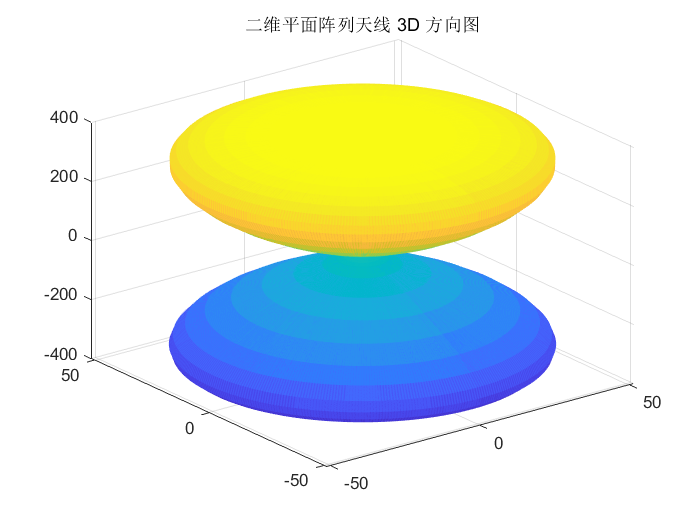

%% 画出3D方向图
figure(2);
surf( (abs(F).* sin(theta))'* sin(phi), ...
    (abs(F).* sin(theta))'* cos(phi), ...
    (abs(F).*cos(theta))'* ones(size(phi)), ...
    'LineStyle','none','EdgeColor','r') ;
%axis equal
title('二维平面阵列天线 3D 方向图');